Q1


for n=[8,10,12]
    H=hilb(n);
    HI=invhilb(n);
    x=ones(n,1);
    b=H*x;
    x1=H\b;
    x2=HI*b;
    disp('x1')
    disp(x1);
    disp('x2');
    disp(x2);
    
    disp('for method 1')
    eta=norm(H*x1-x)/(norm(H)*norm(x));
    err=norm(x1-x)/norm(x);
    cond_num1=cond(H);
    disp('eta');
    disp(eta);
    disp('conditon number')
    disp(cond_num1);
    disp('error')
    disp(err);
    
    eta=norm(H*x2-x)/(norm(H)*norm(x));
    err=norm(x2-x)/norm(x);
    cond_num1=cond(H);
    disp('eta');
    disp(eta);
    disp('conditon number')
    disp(cond_num1);
    disp('error')
    disp(err);
end

x1


     1.000000000007887e+00
     9.999999996257741e-01
     1.000000004419112e+00
     9.999999780253649e-01
     1.000000055026897e+00
     9.999999268851272e-01
     1.000000049236258e+00
     9.999999867722260e-01



x2


     9.999999999559979e-01
     1.000000003802896e+00
     9.999999585562094e-01
     1.000000202096643e+00
     9.999995783446813e-01
     1.000000688245976e+00
     9.999993969696490e-01
     1.000000185066810e+00



for method 1


eta


     4.160478159239459e-01



conditon number


     1.525757556662796e+10



error


     3.787393632254160e-08



eta


     4.160478174940541e-01



conditon number


     1.525757556662796e+10



error


     3.694499567361379e-07



x1


     1.000000000500572e+00
     9.999999550889661e-01
     1.000000983331519e+00
     9.999908694955801e-01
     1.000044286525340e+00
     9.998765881458510e-01
     1.000204778517930e+00
     9.998002151022510e-01
     1.000105740566398e+00
     9.999765822757334e-01



x2


     9.999999984315036e-01
     1.000000097858180e+00
     9.999974447886828e-01
     1.000034339056441e+00
     9.999205735555385e-01
     1.000344464356992e+00
     9.995988256810548e-01
     1.000275899237181e+00
     9.997656904931382e-01
     1.000049949503044e+00



for method 1


eta


     4.206828653188454e-01



conditon number


     1.602502816811318e+13



error


     1.052871412408154e-04



eta


     4.206841601043591e-01



conditon number


     1.602502816811318e+13



error


     2.050870751453798e-04



x1


     9.999999761812168e-01
     1.000003015336616e+00
     9.999051601195813e-01
     1.001293139945377e+00
     9.905104370156915e-01
     1.041742893131150e+00
     8.835566785150567e-01
     1.211020926052178e+00
     7.523304821185069e-01
     1.181578509467286e+00
     9.244305007071151e-01
     1.013628298113950e+00



x2


     9.999999886135473e-01
     1.000001935145427e+00
     9.999654795845352e-01
     1.001032602222757e+00
     9.956734520793198e-01
     9.948516846846474e-01
     9.852900183934992e-01
     1.259798945807859e+00
     8.633637518531678e-01
     1.050286109738394e+00
     9.526298339098744e-01
     1.007281081334568e+00



for method 1


eta


     4.229536851261694e-01



conditon number


     1.621163904747500e+16



error


     1.155171363256130e-01



eta


     4.266673835211290e-01



conditon number


     1.621163904747500e+16



error


     8.720343616751396e-02



n=10;
H=hilb(n);
x=rand(n,1);
b=H*x;
x1=H\b;
r=H*x1-b;
disp([norm(r,inf),norm(x-x1,inf)]);

     1.110223024625157e-16     2.206504576217627e-04



Q2

n=10;
A=diag(ones(n,1)*2)+diag(ones(n-1,1)*(-1),-1)+diag(ones(n-1,1)*(-1),1);
A(1,1)=1;
[L,U]=GENP(A);
disp(L);

     1     0     0     0     0     0     0     0     0     0
    -1     1     0     0     0     0     0     0     0     0
     0    -1     1     0     0     0     0     0     0     0
     0     0    -1     1     0     0     0     0     0     0
     0     0     0    -1     1     0     0     0     0     0
     0     0     0     0    -1     1     0     0     0     0
     0     0     0     0     0    -1     1     0     0     0
     0     0     0     0     0     0    -1     1     0     0
     0     0     0     0     0     0     0    -1     1     0
     0     0     0     0     0     0     0     0    -1     1



disp(U);

     1    -1     0     0     0     0     0     0     0     0
     0     1    -1     0     0     0     0     0     0     0
     0     0     1    -1     0     0     0     0     0     0
     0     0     0     1    -1     0     0     0     0     0
     0     0     0     0     1    -1     0     0     0     0
     0     0     0     0     0     1    -1     0     0     0
     0     0     0     0     0     0     1    -1     0     0
     0     0     0     0     0     0     0     1    -1     0
     0     0     0     0     0     0     0     0     1    -1
     0     0     0     0     0     0     0     0     0     1



D=diag(diag(A));
A1=L*D*L';
disp(A1);

     1    -1     0     0     0     0     0     0     0     0
    -1     3    -2     0     0     0     0     0     0     0
     0    -2     4    -2     0     0     0     0     0     0
     0     0    -2     4    -2     0     0     0     0     0
     0     0     0    -2     4    -2     0     0     0     0
     0     0     0     0    -2     4    -2     0     0     0
     0     0     0     0     0    -2     4    -2     0     0
     0     0     0     0     0     0    -2     4    -2     0
     0     0     0     0     0     0     0    -2     4    -2
     0     0     0     0     0     0     0     0    -2     4



ch=chol(A);
disp(ch);

     1    -1     0     0     0     0     0     0     0     0
     0     1    -1     0     0     0     0     0     0     0
     0     0     1    -1     0     0     0     0     0     0
     0     0     0     1    -1     0     0     0     0     0
     0     0     0     0     1    -1     0     0     0     0
     0     0     0     0     0     1    -1     0     0     0
     0     0     0     0     0     0     1    -1     0     0
     0     0     0     0     0     0     0     1    -1     0
     0     0     0     0     0     0     0     0     1    -1
     0     0     0     0     0     0     0     0     0     1



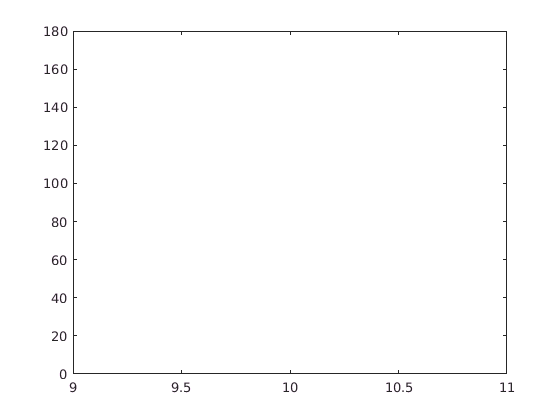

N=50;
condofH=[];
N_it=zeros(1,N);
for i=1:N
    hn=hilb(n);
    N_it=n;
    condofH=[condofH,cond(hn,2)];
end
x=1:50;
y=(1+sqrt(2)).^(4*x)./sqrt(x);

plot(N_it,log(y));

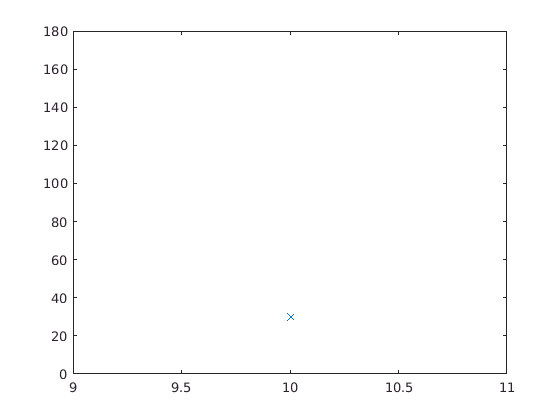

plot(N_it,log(condofH),'x',N_it,log(y));

plot(N_it, log(condofH),'x', N_it,log(y))
title('Conditional Number growth of Hilbert Matrix: Theoretical vs Matlab')
xlabel('N', 'fontsize', 16)
ylabel('log(cond(Hn))','fontsize', 16)
lgd = legend ('Location', 'northwest')

lgd =   Legend (data1, data2, data3, data4, data5, data6, data7, data8, data9, data10, data11, data12, data13, data14, data15, data16, data17, data18, data19, data20, data21, data22, data23, data24, data25, data26, data27, data28, data29, data30, data31, data32, data33, data34, data35, data36, data37, data38, data39, data40, data41, data42,…) with properties:

         String: {1×50 cell}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 9
       Position: [1.541666666666666e-01 -9.591269309085518e-01 1.499999977116075e-01 1.853571375352997e+00]
          Units: 'normalized'

  Show all properties


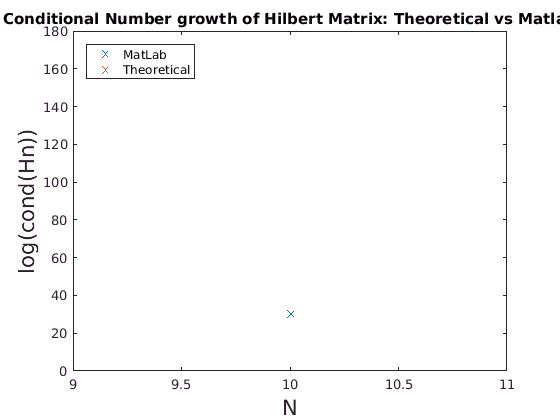

legend('MatLab', 'Theoretical')

legend('show')


function [L, U] = GENP(A)
    [~, n] = size(A);
    for k = 1:n-1
        A(k+1:n,k) = A(k+1:n,k)/A(k,k);
        j = k+1:n;
        A(j,j) = A(j,j)-A(j,k)*A(k,j);
    end
    L = eye(n,n)+ tril(A,-1);
    U = triu(A); 
end